# a) Transient equilibrium: (self made solver)

#  
$$^{99}Mo-^{99m}Tc
$$


clc,clearvars,clf

tHalfP=65.94; %half life of parent(Mo-90) in hours
tHalfD1=6.04;   %half life of progeny(Tc-99m) in hours
tHalfD2=210000*365*24; %half life of progeny (Tc-99) in hours
%decay constants
lambdaP=log(2)/tHalfP;  
lambdaD1=log(2)/tHalfD1;
lambdaD2=log(2)/tHalfD2;

%differential equations
dN1=@(t,NP,ND,ND2)(-lambdaP)*NP;
dN2=@(t,NP,ND,ND2) lambdaP*NP-lambdaD1*ND;
dN3=@(t,NP,ND,ND2)lambdaD1*ND;
%using rk4 function to solve the system of ODE
[t,NP,ND,ND2]=rk4_2(dN1,dN2,dN3,0,100,1/lambdaP,0,0,72);

%activity
AP=lambdaP*NP;
AD1=0.88*lambdaD1*ND;
AD2=0.12*lambdaD2*ND2;

#### Plotting activity vs. time graph

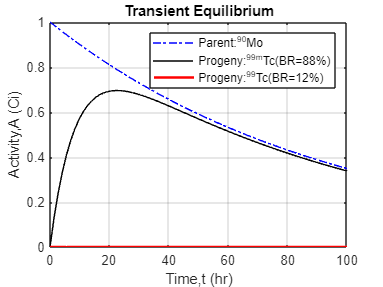

figure(1)
plot(t,AP,'b-.') %plotting Mo-90 activity vs. time
hold on
plot(t,AD1,'k') %plotting Tc-99m activity vs. time
plot(t,AD2,'r','linewidth',2) %plotting Tc-99 activity vs. time
xlabel('Time,t (hr)')
ylabel('Activity,A (Ci)')
legend('Parent:^{90}Mo','Progeny:^{99m}Tc(BR=88%)','Progeny:^{99}Tc(BR=12%)')
title('Transient Equilibrium')
grid on

#### Plotting Relative no. of atoms vs. time graph

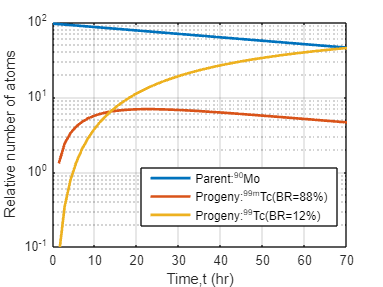

figure(2)

semilogy(t,NP,'linewidth',2)
%axis scaling for better appearance
axis([0 70 10e-2 10e1]) 
hold on
semilogy(t,ND,'linewidth',2)
semilogy(t,ND2,'linewidth',2)
xlabel('Time,t (hr)')
ylabel('Relative number of atoms')
legend('Parent:^{90}Mo','Progeny:^{99m}Tc(BR=88%)','Progeny:^{99}Tc(BR=12%)')
grid on

legend("Position", [0.3823,0.21792,0.48564,0.19512])

#### Time when progeny reaches maximum activity

[maxTcmAct,I]=max(AD1);%maximum Tc-99m activity and that specific index 
tMax=t(I);  %Time to reach maximum activity
fprintf('Time when ''Tc-99m'' reaches maximum activity= %.4f hr',tMax)

Time when 'Tc-99m' reaches maximum activity= 22.2222 hr